format long
p_3 = 1/216;
p_2 = 5/72;
p_1 = 25/72;
q = 125/216; 

syms x
p_sym = (1/216)*x^4 + (5/72)*x^3 + (25/72)*x^2 - x + (125/216);
lambda_sym = solve(p_sym, x);
l_1 = double(lambda_sym(1))

l_1 =      1


l_2 = double(lambda_sym(2))

l_2 =    1.132264310167907


l_3 = double(lambda_sym(3))

l_3 =  -8.566132155083954 - 6.084376001892327i


l_4 = double(lambda_sym(4))

l_4 =  -8.566132155083954 + 6.084376001892327i


C1 =   50.930992923753365


C2 =  -50.930992923661108


C3 =      -4.612710300003380e-11 - 2.882390846223280e-11i


C4 =      -4.612710300003380e-11 + 2.882390846223280e-11i


d_W =    0.000000000000003
   5.969529708258348
  11.048080382533247
  15.117807194738766
  18.045280372728243
  19.679403898556288
  19.849219813952644
  18.361071565945707
  14.983635961496020
   9.671085625865729


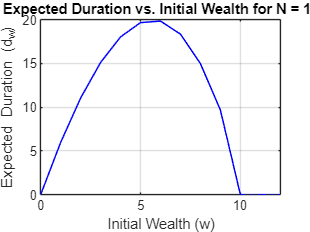

C1 =    1.256623804857695


C2 =   -1.256623804857695


C3 =      -2.731610395469569e-51 - 4.084652884774788e-51i


C4 =      -2.731610395469569e-51 + 4.084652884774788e-51i


d_W = 1.0e+02 *

  -0.000000000000000
   0.125396758722511
   0.250573685589883
   0.375501704693443
   0.500147894419515
   0.624474978799900
   0.748440751586181
   0.871997424149607
   0.995090887131413
   1.117659874435824


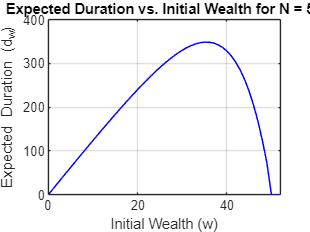

C1 =    0.005027422780228


C2 =   -0.005027422780228


C3 =     -4.838190262549937e-103 -8.982733463752648e-102i


C4 =     -4.838190262549937e-103 +8.982733463752648e-102i


d_W = 1.0e+02 *

  -0.000000000000000
   0.127052174043352
   0.254103468597018
   0.381153767335900
   0.508202938549244
   0.635250833105661
   0.762297282149004
   0.889342094489484
   1.016385053649725
   1.143425914520122


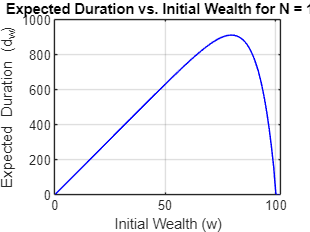


N_values = [10, 50, 100]; 
n = length(N_values);

for i = 1:n
    N = N_values(i);

    % Solve for coefficients
    syms c_1 c_2 c_3 c_4;
    [c_1, c_2, c_3, c_4] = solve( ...
        c_1*(l_1)^(0) + c_2*(l_2)^(0) + c_3*(l_3)^(0) + c_4*(l_4)^(0) - (0)/(3*p_3 + 2*p_2 + p_1 - q) == 0, ...
        c_1*(l_1)^(N) + c_2*(l_2)^(N) + c_3*(l_3)^(N) + c_4*(l_4)^(N) - (N)/(3*p_3 + 2*p_2 + p_1 - q) == 0, ...
        c_1*(l_1)^(N+1) + c_2*(l_2)^(N+1) + c_3*(l_3)^(N+1) + c_4*(l_4)^(N+1) - (N+1)/(3*p_3 + 2*p_2 + p_1 - q) == 0, ...
        c_1*(l_1)^(N+2) + c_2*(l_2)^(N+2) + c_3*(l_3)^(N+2) + c_4*(l_4)^(N+2) - (N+2)/(3*p_3 + 2*p_2 + p_1 - q) == 0);

    C1 = double(c_1) % Extract values
    C2 = double(c_2)
    C3 = double(c_3)
    C4 = double(c_4)

    d_W = zeros(1, N+3);
    
    for W = 1:N+3
        d_W(W) = C1*(l_1)^(W-1) + C2*(l_2)^(W-1) + C3*(l_3)^(W-1) + C4*(l_4)^(W-1) - (W-1)/(3*p_3 + 2*p_2 + p_1 - q) ;
    end

    d_W = double(d_W)'
    
    figure;
    plot(0:N+2, d_W, 'b', 'LineWidth', 1);
    xlabel('Initial Wealth (w)');
    ylabel('Expected Duration (d_w)');
    title(['Expected Duration vs. Initial Wealth for N = ', num2str(N)]);
    grid on;
    xlim([0 N+2])

end